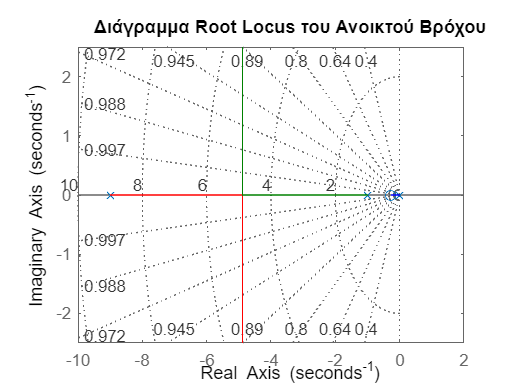

%% Ανάλυση Root Locus και Απόκριση Βήματος & Ράμπας σε PI Ελεγκτή

s = tf('s');
Gp = tf([10], [1 10 9]);      % Δορυφόρος
kp = 5; ki = 1.5;
Gc = kp + ki/s;              % PI Ελεγκτής
OL = series(Gc, Gp);         % Ανοικτός βρόχος
CL = feedback(OL, 1);        % Κλειστός βρόχος με ανάδραση

%% Root Locus
figure;
rlocus(OL); grid on;
title('Διάγραμμα Root Locus του Ανοικτού Βρόχου');

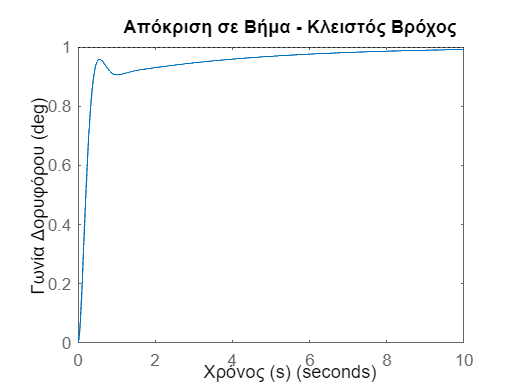


%% Step απόκριση
figure;
step(CL, 0:0.01:10);
title('Απόκριση σε Βήμα - Κλειστός Βρόχος');
xlabel('Χρόνος (s)');
ylabel('Γωνία Δορυφόρου (deg)');


info = stepinfo(CL);
fprintf("=== Απόκριση Βήματος ===\n");

=== Απόκριση Βήματος ===


fprintf("Χρόνος Ανόδου: %.2f s\n", info.RiseTime);

Χρόνος Ανόδου: 0.34 s


fprintf("Ύπερκορύφωση: %.1f %%\n", info.Overshoot);

Ύπερκορύφωση: 0.0 %


fprintf("Καθίζηση: %.2f s\n", info.SettlingTime);

Καθίζηση: 6.71 s


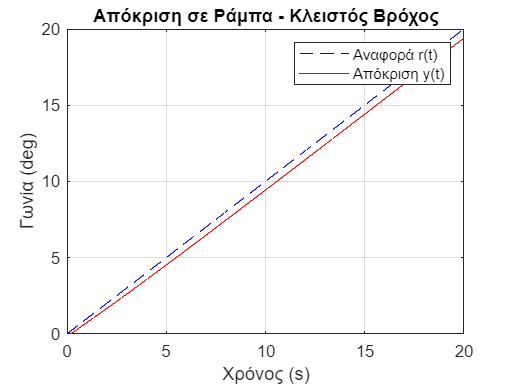


%% Απόκριση σε Ράμπα
t = 0:0.01:20;
ramp_input = t;  % r(t) = t
[y_ramp, t_ramp] = lsim(CL, ramp_input, t);  
figure;
plot(t_ramp, ramp_input, '--b', 'DisplayName', 'Αναφορά r(t)');
hold on;
plot(t_ramp, y_ramp, '-r', 'DisplayName', 'Απόκριση y(t)');
xlabel('Χρόνος (s)');
ylabel('Γωνία (deg)');
title('Απόκριση σε Ράμπα - Κλειστός Βρόχος');
legend;
grid on;


% Υπολογισμός RMSE
rmse = sqrt(mean((ramp_input - y_ramp).^2));
fprintf("=== Απόκριση Ράμπας ===\n");

=== Απόκριση Ράμπας ===


fprintf("Σφάλμα RMSE: %.4f deg\n", rmse);

Σφάλμα RMSE: 11.0570 deg
Σφάλμα RMSE: 11.0484 deg
Σφάλμα RMSE: 11.0399 deg
Σφάλμα RMSE: 11.0313 deg
Σφάλμα RMSE: 11.0227 deg
Σφάλμα RMSE: 11.0142 deg
Σφάλμα RMSE: 11.0056 deg
Σφάλμα RMSE: 10.9970 deg
Σφάλμα RMSE: 10.9885 deg
Σφάλμα RMSE: 10.9799 deg
Σφάλμα RMSE: 10.9714 deg
Σφάλμα RMSE: 10.9628 deg
Σφάλμα RMSE: 10.9543 deg
Σφάλμα RMSE: 10.9457 deg
Σφάλμα RMSE: 10.9372 deg
Σφάλμα RMSE: 10.9286 deg
Σφάλμα RMSE: 10.9201 deg
Σφάλμα RMSE: 10.9116 deg
Σφάλμα RMSE: 10.9030 deg
Σφάλμα RMSE: 10.8945 deg
Σφάλμα RMSE: 10.8860 deg
Σφάλμα RMSE: 10.8774 deg
Σφάλμα RMSE: 10.8689 deg
Σφάλμα RMSE: 10.8604 deg
Σφάλμα RMSE: 10.8519 deg
Σφάλμα RMSE: 10.8433 deg
Σφάλμα RMSE: 10.8348 deg
Σφάλμα RMSE: 10.8263 deg
Σφάλμα RMSE: 10.8178 deg
Σφάλμα RMSE: 10.8093 deg
Σφάλμα RMSE: 10.8008 deg
Σφάλμα RMSE: 10.7923 deg
Σφάλμα RMSE: 10.7838 deg
Σφάλμα RMSE: 10.7753 deg
Σφάλμα RMSE: 10.7668 deg
Σφάλμα RMSE: 10.7583 deg
Σφάλμα RMSE: 10.7498 deg
Σφάλμα RMSE: 10.7413 deg
Σφάλμα RMSE: 10.7328 deg
Σφάλμα RMSE: 10.7244 deg
